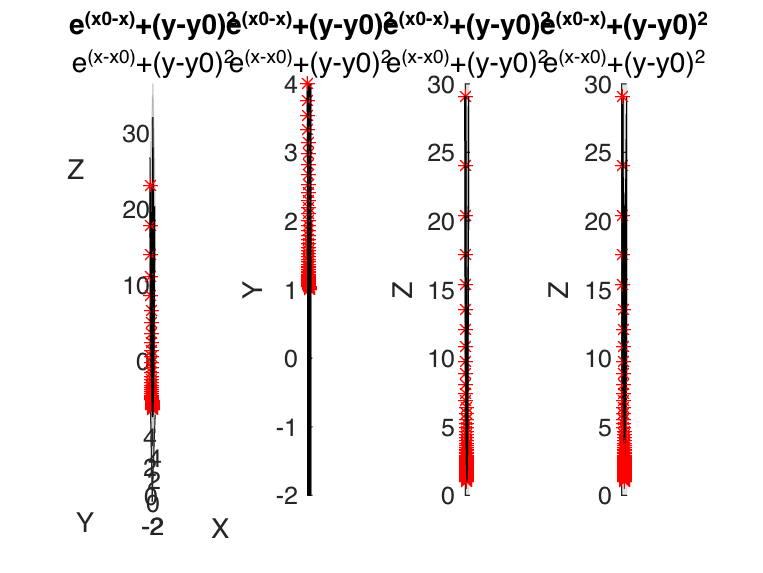

clear all
close all
clc

x1 = -2:0.1:1;
y1 = -2:0.1:4;
[x1,y1] = meshgrid(x1,y1);
z1 = exp(1-x1)+(y1-1).^2;
x2 = 1:0.1:4;
y2 = -2:0.1:4;
[x2,y2] = meshgrid(x2,y2);
z2 = exp(x2-1)+(y2-1).^2;

x0 = -2;
y0 = 4;
EPS = 0.0101;
px = 0.01;
py = 0.04;
point = Tidu2(x0,y0,EPS,px,py);

figure
subplot(141)
surf(x1,y1,z1)    %绘制三维表面图形
hold on
surf(x2,y2,z2)
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("e^{(x0-x)}+(y-y0)^2","e^{(x-x0)}+(y-y0)^2")

subplot(142)
surf(x1,y1,z1)    %绘制三维表面图形
hold on
surf(x2,y2,z2)
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("e^{(x0-x)}+(y-y0)^2","e^{(x-x0)}+(y-y0)^2")
view(0,90)

subplot(143)
surf(x1,y1,z1)    %绘制三维表面图形
hold on
surf(x2,y2,z2)
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("e^{(x0-x)}+(y-y0)^2","e^{(x-x0)}+(y-y0)^2")
view(0,0)

subplot(144)
surf(x1,y1,z1)    %绘制三维表面图形
hold on
surf(x2,y2,z2)
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');
axis on;xlabel('X');ylabel('Y');zlabel('Z');
title("e^{(x0-x)}+(y-y0)^2","e^{(x-x0)}+(y-y0)^2")
view(-90,0)


zo=zeros((size(point,1)-size(z1,1)),size(z1,2));
data13=[point,[x1;zo],[y1;zo],[z1;zo],[x2;zo],[y2;zo],[z2;zo]];
csvwrite('data13.csv',data13);


function point = Tidu2(x,y,EPS,px,py)
    syms xx yy
      fun1 = exp(1-xx)+(yy-1)^2;
      fun2 = exp(xx-1)+(yy-1)^2;
    dfunx1 = -exp(1-xx);
    dfunx2 = exp(xx-1);
     dfuny = 2*yy-2;
    if x<=1
        a = eval(subs(fun1,[xx,yy],[x,y]));
    else
        a = eval(subs(fun2,[xx,yy],[x,y]));
    end
    b = a+1;
    n=1;
    point(n,:) = [x y a];
    while (abs(a-b) >= EPS)      
        if x<=1
            a = eval(subs(fun1,[xx,yy],[x,y]));
            x = x - px*eval(subs(dfunx1,xx,x));
            y = y - py*eval(subs(dfuny,yy,y));
            b = eval(subs(fun1,[xx,yy],[x,y])); 
        else
            a = eval(subs(fun2,[xx,yy],[x,y]));
            x = x - px*eval(subs(dfunx2,xx,x));
            y = y - py*eval(subs(dfuny,yy,y));
            b = eval(subs(fun2,[xx,yy],[x,y])); 
        end
        n = n+1;
        point(n,:) = [x y b]; 
    end
end
